% Load the lighthouse image
load lighthouse.mat; 
ww = xx;

% Check the size of the image
whos ww

  Name        Size               Bytes  Class     Attributes

  ww        326x426            1111008  double              



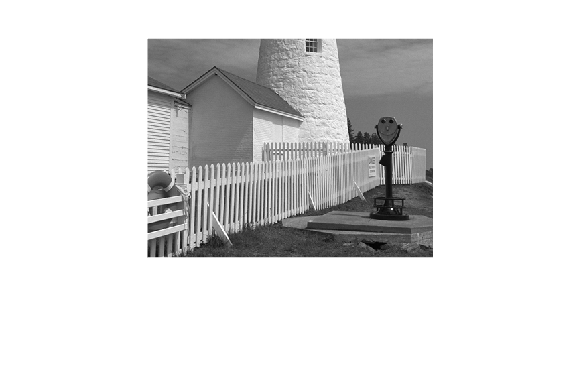


% Display the image with the correct colormap
imshow(ww, []); 
colormap(gray(256));

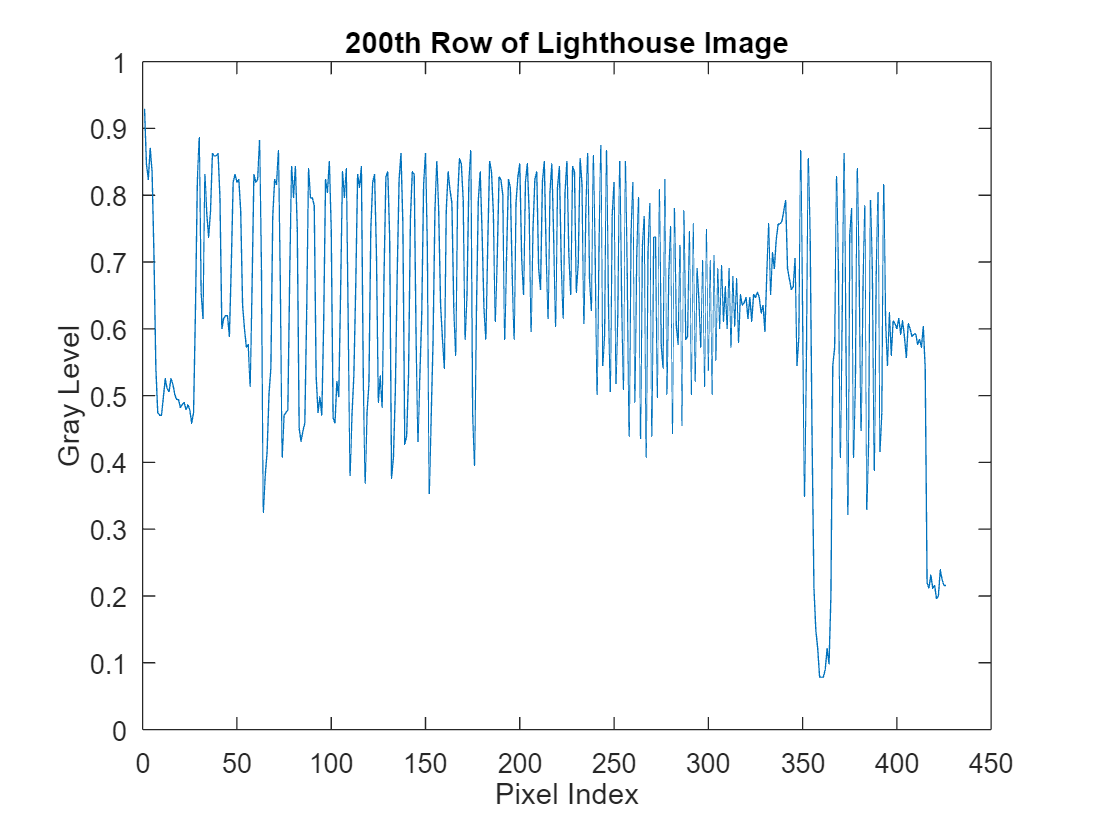


% Extract the 200th row
ww200 = ww(200, :);

% Plot the 200th row as a 1-D discrete-time signal
figure;
plot(ww200);
title('200th Row of Lighthouse Image');
xlabel('Pixel Index');
ylabel('Gray Level');

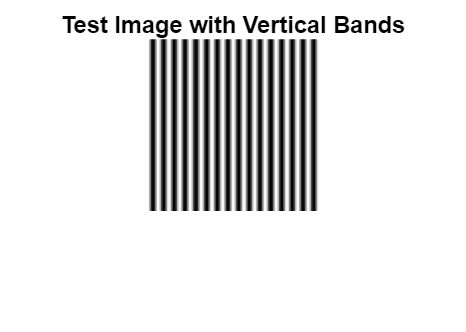


% Generate the image
xpix = ones(256, 1) * cos(2 * pi * (0:255) / 16);

% Display the image
figure;
imshow(xpix, []);
title('Test Image with Vertical Bands');
colormap(gray(256));

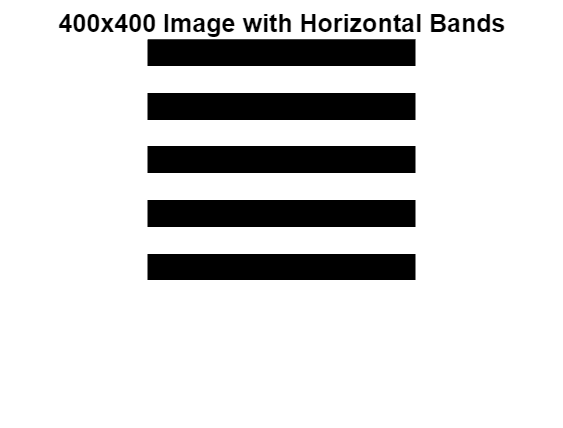


% Generate the image with horizontal bands
horizontal_bands = repmat([zeros(40, 400); ones(40, 400)], 5, 1);

% Display the image
figure;
imshow(horizontal_bands, []);
title('400x400 Image with Horizontal Bands');
colormap(gray(256));

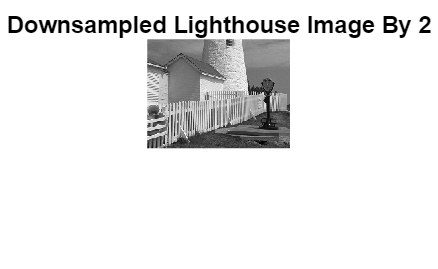


% Load the lighthouse image
load lighthouse.mat;

% Downsample the image by a factor of 2
wp = ww(1:2:end, 1:2:end);

% Display the downsampled image
figure;
imshow(wp, []);
title('Downsampled Lighthouse Image By 2');
colormap(gray(256));

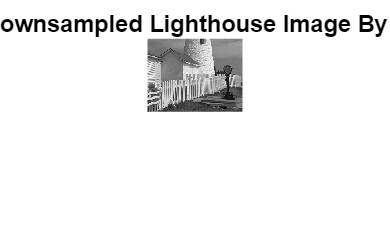





%Lab Exercise 3.2: Reconstruction of Images
% Create the downsampled image by a factor of 3
xx3 = ww(1:3:end, 1:3:end);

% Display the downsampled image
figure;
imshow(xx3, []);
title('Downsampled Lighthouse Image By 3');
colormap(gray(256));

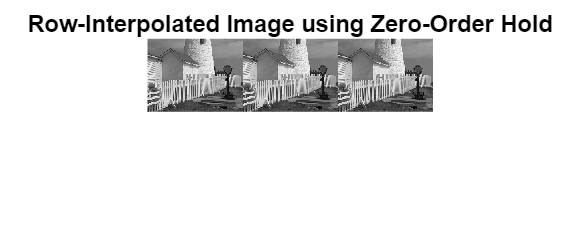


% Zero-order hold interpolation along rows
xholdrows = repmat(xx3, 1, 3);

% Display the row-interpolated image
figure;
imshow(xholdrows, []);
title('Row-Interpolated Image using Zero-Order Hold');
colormap(gray(256));

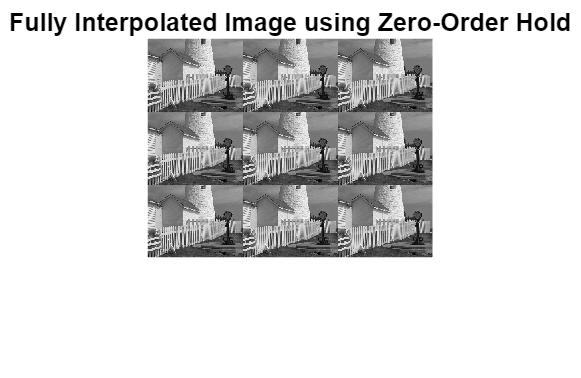


% Zero-order hold interpolation along columns
xhold = repmat(xholdrows, 3, 1);

% Display the fully interpolated image
figure;
imshow(xhold, []);
title('Fully Interpolated Image using Zero-Order Hold');
colormap(gray(256));

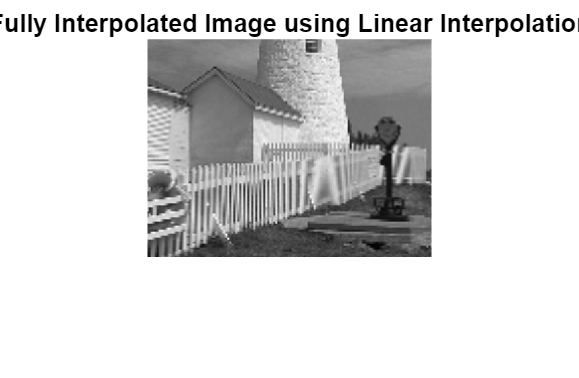


% Linear interpolation along rows
n1 = 1:size(xx3, 2);
tti = 1:1/3:size(xx3, 2);
xholdrows_linear = interp1(n1, xx3', tti)';
 
% Linear interpolation along columns
n2 = 1:size(xholdrows_linear, 1);
tti2 = 1:1/3:size(xholdrows_linear, 1);
xxlinear = interp1(n2, xholdrows_linear, tti2);

% Display the linearly interpolated image
figure;
imshow(xxlinear, []);
title('Fully Interpolated Image using Linear Interpolation');
colormap(gray(256));

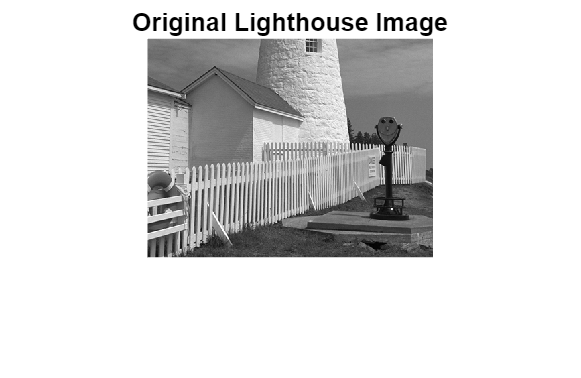


% Display the original image
figure;
imshow(ww, []);
title('Original Lighthouse Image');
colormap(gray(256));

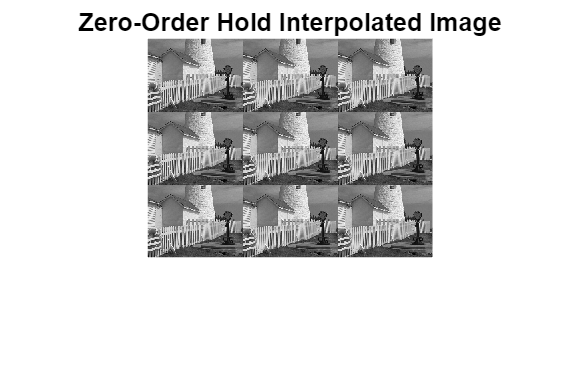


% Display the zero-order hold interpolated image
figure;
imshow(xhold, []);
title('Zero-Order Hold Interpolated Image');
colormap(gray(256));

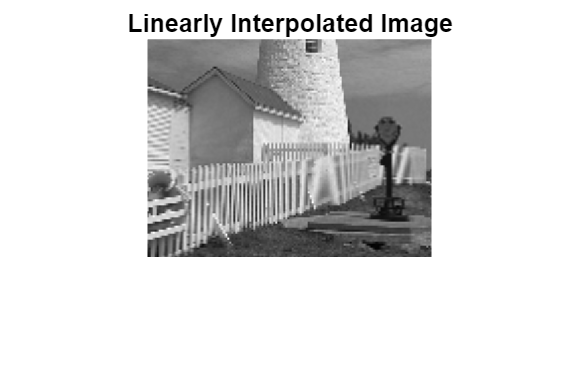


% Display the linearly interpolated image
figure;
imshow(xxlinear, []);
title('Linearly Interpolated Image');
colormap(gray(256));